**References**

 
% Barten, Peter G, Contrast Sensivity of the Human Eye and Its Effects on Image Quality (1999)
% A. B. Watson, "A formula for human retinal ganglion cell receptive field density as a function of visual field location," J. Vis. 14, 1–17 (2014).
% S. J. Daly, "Visible differences predictor: an algorithm for the assessment of image fidelity," in Human Vision, Visual Processing, and Digital Display III, B. E. Rogowitz, ed. (SPIE, 1992), Vol. 1666, p. 2.
% L. N. Thibos, D. L. Still, and A. Bradley, "Characterization of spatial aliasing and contrast sensitivity in peripheral vision," Vision Res. 36, 249–258 (1996).

clear all; 
close all;
clc;

**Variables of Barten CSF Model**

% Frequency range in cpd
u   = 0.1:0.01:100;

% Eccentricity in degrees
e   = 30;

% Average luminance of the observed object in cd/m^2
L   = 80;

% Field diameter in degrees
D   = 2.67;

% Signal to Noise ratio
k   = 3;

% Constant for quantom efficiency
eta0 = 0.03;

% constanct for the eye MTF
sigma0 = 0.50;

% eccentricity constant (can be different for various subjects)
eg      = 3.3;

% Spatial frequency above which the lateral inhibition ceases as a function of eccentricity in Fovea
u00     = 7;

% Density of total Retinal ganglion cells in fovea
Ng0       = 33163.2;

load("thibosDetection30Deg.mat")
load("thibosResolution30deg.mat")

### **Plot**

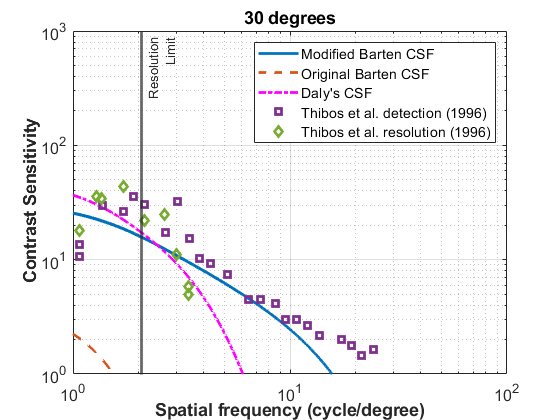

fig = figure;

for i= 1:length(e)
    
    % Andrew Watson formula for temporal midget density
    a         = 0.9851;
    r2        = 1.058;
    re        = 22.14;
    rm        = 41.03;
    Ngm_temporal(i) = Ng0 * (0.8928*(1+e(i)/rm)^-1) * ( a * (1+(e(i)/r2)).^-2 + (1-a) * exp(-e(i)/re));
    
    % Andrew Watson formula for nasal midget density
    a_n       = 0.9729;
    r2_n      = 1.084;
    re_n      = 7.633;
    rm_n      = 41.03;
    Ngm_nasal(i) = Ng0 * (0.8928*(1+e(i)/rm_n)^-1) * ( a_n * (1+(e(i)/r2_n)).^-2 + (1-a_n) * exp(-e(i)/re_n));
    
    % For binocular use: Ngm(i)       = mean([Ngm_temporal(i),Ngm_nasal(i)]);
    Ngm(i)       = Ngm_nasal(i);
    
    nyquistF(i)  = sqrt(0.5*Ngm(i)/(2*sqrt(3)));     
    modifiedBarCSF(i,:) = bartenDetection(u,e(i),L,D,k,eta0,sigma0,eg,u00);
    originalBarCSF(i,:) = bartenMC(u,e(i),L,D,k,eta0,sigma0,eg,u00);
    daly(i,:)        = dalyCSF(u,0,80,D^2*pi/4,1,30);
    
end

    titles = {'30 degrees'};
    
    loglog(u,modifiedBarCSF(1,:),'-',u,originalBarCSF(1,:),'--', u ,daly(i,:),'-.m', LineWidth=2);
    title(titles{1})
    ylim([1 1000]);
    xlim([1 100]);
    xline(nyquistF,'-',{'Resolution','Limit'},LineWidth=2)
    hold on 
    loglog(thibosDetection30deg(:,1),thibosDetection30deg(:,2),'s',LineWidth=2)
    loglog(thibosResolution30deg(:,1),thibosResolution30deg(:,2),'d',LineWidth=2)
    grid on
    legend('Modified Barten CSF','Original Barten CSF',"Daly's CSF",'','Thibos et al. detection (1996)','Thibos et al. resolution (1996)')
    set(gca,'fontsize', 12)

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Contrast Sensitivity','FontWeight','bold');
xlabel(han,'Spatial frequency (cycle/degree)','FontWeight','bold');
set(gca,'fontsize', 12)

freqDet = thibosDetection30deg(:,1);

orgBarDet = bartenMC(freqDet,30,L,D,k,eta0,sigma0,eg,u00);
modBarDet = bartenDetection(freqDet,30,L,D,k,eta0,sigma0,eg,u00);
dalyDet   = dalyCSF(freqDet,0,80,D^2*pi/4,1,30);

detOrgEstErr  = sigmaEst(orgBarDet, thibosDetection30deg(:,2))    

detOrgEstErr = 16.4536

detModEstErr  = sigmaEst(modBarDet, thibosDetection30deg(:,2))

detModEstErr = 8.5939

detDalyEstErr = sigmaEst(dalyDet, thibosDetection30deg(:,2))

detDalyEstErr = 10.5565


freqRes = thibosResolution30deg(:,1);

orgBarRes = bartenMC(freqRes,30,L,D,k,eta0,sigma0,eg,u00);
modBarRes = bartenDetection(freqRes,30,L,D,k,eta0,sigma0,eg,u00);
daly      = dalyCSF(freqRes,0,80,D^2*pi/4,1,30);

resOrgEstErr  = sigmaEst(orgBarRes, thibosResolution30deg(:,2))    

resOrgEstErr = 28.1559

resModEstErr  = sigmaEst(modBarRes, thibosResolution30deg(:,2))

resModEstErr = 13.1122

resDalyEstErr = sigmaEst(daly, thibosResolution30deg(:,2))

resDalyEstErr = 11.9354